% AE6511 Hw5 Problem 3 MATLAB code
% Tomoki Koike clear all; close all; clc;  % housekeeping commands
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

## GPOP-II

% All data required by user functions is stored in auxdata
auxdata.alpha = 0.2;

% Boundary conditions of the problem
t0 = 0;
x0 = 1;
y0 = 1;
xf = 0;
yf = 0;

% Limits on variables
tfmin = 0; tfmax = 3;
xmin = xf; xmax = x0;
ymin = yf; ymax = y0;
thetamin = 0; thetamax = 2*pi;

% Set up problem using data provided above
bounds.phase.initialtime.lower = t0;
bounds.phase.initialtime.upper = t0;
bounds.phase.finaltime.lower = tfmin;
bounds.phase.finaltime.upper = tfmax;
bounds.phase.initialstate.lower = [x0, y0];
bounds.phase.initialstate.upper = [x0, y0];
bounds.phase.state.lower = [xmin, ymin];
bounds.phase.state.upper = [xmax, ymax];
bounds.phase.finalstate.lower = [xf, yf];
bounds.phase.finalstate.upper = [xf, yf];
bounds.phase.control.lower = thetamin;
bounds.phase.control.upper = thetamax;

% Provide guess of solution
guess.phase.time = [t0; tfmax];
guess.phase.state(:,1) = [x0; xf];
guess.phase.state(:,2) = [y0; yf];
guess.phase.control = [thetamin; 4];
% guess.phase.integral = 0;

% Provide mesh refinement method and initial mesh 
mesh.method       = 'hp-PattersonRao';
mesh.tolerance    = 1e-6;
mesh.maxiterations = 45;
mesh.colpointsmin = 4;
mesh.colpointsmax = 10;

% Configure setup using the infromation provided
setup.name= 'hw5-p3-system'

setup = struct with fields:
            name: 'hw5-p3-system'
       functions: [1×1 struct]
    displaylevel: 2
          bounds: [1×1 struct]
           guess: [1×1 struct]
            mesh: [1×1 struct]
         auxdata: [1×1 struct]
             nlp: [1×1 struct]
     derivatives: [1×1 struct]
          method: 'RPM-Differentiation'


setup.functions.continuous = @hw5p3systemContinuous;
setup.functions.endpoint = @hw5p3systemEndpoint;
setup.displaylevel = 2;
setup.bounds = bounds;
setup.guess = guess;
setup.mesh = mesh;
setup.auxdata = auxdata;
setup.nlp.solver = 'ipopt';
setup.derivatives.supplier = 'sparseCD';
setup.derivatives.derivativelevel = 'second';
setup.method = 'RPM-Differentiation';

% Solve problem
output = gpops2(setup);

 ___________________________________________________________________ 
|                                                                   |
|            __________  ____  ____  _____        ________          |
|           / ____/ __ \/ __ \/ __ \/ ___/       /  _/  _/          |
|          / / __/ /_/ / / / / /_/ /\__ \ _____  / / / /            |
|         / /_/ / ____/ /_/ / ____/___/ //____/_/ /_/ /             |
|         \____/_/    \____/_/    /____/      /___/___/             |
|                                                                   |
| GPOPS-II Version 2.5.  Release Date: Aug 2018                     |
|___________________________________________________________________|
|                                                                   |
| GPOPS-II Copyright (c) 2013-2019 Michael Patterson & Anil V. Rao. |
|___________________________________________________________________|
|                                                                   |
| Downloading, using

## Plotting

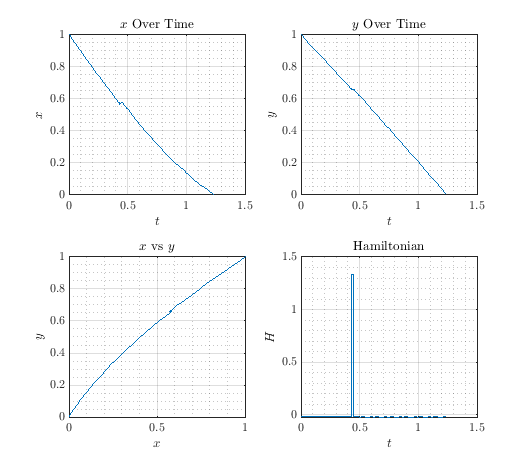

tspan = output.result.solution.phase.time;
states = output.result.solution.phase.state;
costates = output.result.solution.phase.costate;
control = output.result.solution.phase.control;
x = states(:,1);
y = states(:,2);
lambda1 = costates(:,1);
lambda2 = costates(:,2);

xdot = cos(control) - 0.2 * (3*y - y.^3);
ydot = sin(control);

% Hamiltonian 
H = 1 + lambda1 .* xdot + lambda2 .* ydot;

fig = figure("Renderer","painters","Position",[60 60 900 800]);
    % x1 vs t
    subplot(2,2,1)
    plot(tspan, x)
    title('$x$ Over Time')
    xlabel('$t$')
    ylabel('$x$')
    grid on; grid minor; box on;
    % x2 vs t
    subplot(2,2,2)
    plot(tspan, y)
    title('$y$ Over Time')
    xlabel('$t$')
    ylabel('$y$')
    grid on; grid minor; box on;
    % x_1 - x_2 
    subplot(2,2,3)
    plot(x, y)
    title('$x$ vs $y$')
    xlabel('$x$')
    ylabel('$y$')
    grid on; grid minor; box on;
    % Hamiltonian 
    subplot(2,2,4)
    plot(tspan, H)
    title('Hamiltonian')
    xlabel('$t$')
    ylabel('$H$')
    grid on; grid minor; box on;

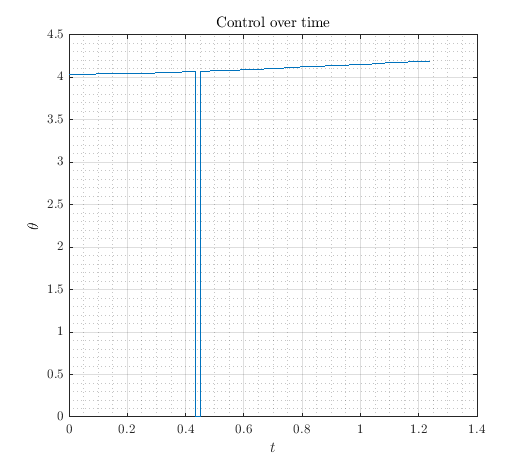

% Control
fig = figure("Renderer","painters","Position",[60 60 900 800]);
    plot(tspan, control)
    xlabel('$t$')
    ylabel('$\theta$')
    title('Control over time')
    grid on; grid minor; box on;

% The minimum time 
disp(output.result.objective)

## Functions

function phaseout = hw5p3systemContinuous(input)
    constants = input.auxdata;
    alpha = constants.alpha;

    x = input.phase(1).state(:,1);
    y = input.phase(1).state(:,2);
    theta = input.phase(1).control(:,1);

    u = -alpha * (3*y - y.^3);

    xdot = cos(theta) + u;
    ydot = sin(theta);

    phaseout.dynamics = [xdot, ydot];
end

function output = hw5p3systemEndpoint(input)
    output.objective = input.phase(1).finaltime;
end